# Signal Based PM

## Introduction

Before the final solution was developed in the whole dataset, the smaller reduced dataset was used for experiments and planning algorithms. 

## Import datastore

Full datastore contain 4840 members. Each member has information from one mesurement, and extracted features from all signals:

- Measured signals

- Setting parameters (valves, dampers, load)

- Power spectum calculated from measured signals

- Statistical and Frequency features extracted from signals

From every signal in dataset statistical features were calculated. Using Welch's power spectral density estimation frequency features were calculated too. 

Original dataset contain 6 large .mat files. Those files was devided to members, for better memory perfomance during the feature extraction and writing output to files back.

clc; clear all; close all;
has_data = false

has_data = logical
   0


if has_data
    run import_full_datastore.m
    datastore 
end  

Datastore handler functions *readData *and *writeData *were coded with respect to members.

## Data exploration

There are types of sensors:

- Linear encoder

- Flow sensor

- Pressure sensor

- Temperature sensor

- Accelerometer

- Strain gauge

- Microphones

- Proximity sensors

The whole dataset was divided into 20 Labels by place of fault accumulate: 

- Healthy

- Throlette valve 1

- Throlette valve 2 

- Small damper bottom

- Small damper upper

- Large dampers 

- and combinations of these faults ...

addpath("scripts/");
data_test = load("data_test/data10_1_1.mat").data

data_test = 1×66 table
       FlowExtrusion         FlowContraction          AirPressure        AccelerometerMoving_axisY    AccelerometerMoving_axisZ    AccelerometerStatic_axisY    AccelerometerStatic_axisZ        StrainGauge        ProximitySensor_bottom    ProximitySensor_upper       LeverPosition           MIC_uBumper             MIC_bBumper             MIC_Ambient          Temp_Cylinder      Temp_Ambient          outValveHP             outValveWP          FaultCode     Settings.Load    ThrottleValve1    ThrottleValve2    SmallDamper_upper    LargeDamper_upper    SmallDamp

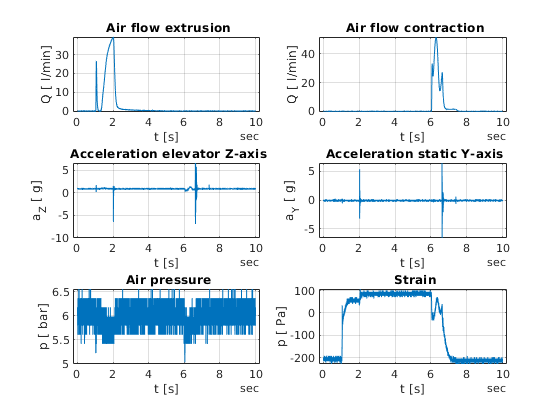

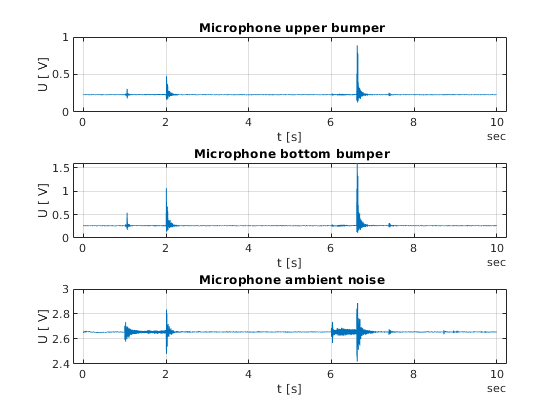

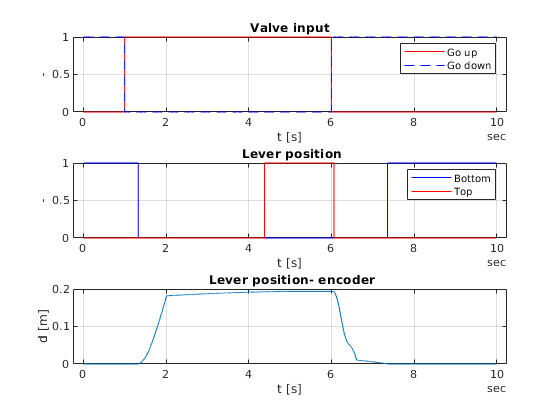

data_plot(data_test)

### Raw vs Preprocess

Some signals, such as Encoder, are very accurate. There is no preprocessing needed to apply. Signals noisier (Pressure signal or Strain) has to be preprocessed and applied some noise reduction algorithms. However, during experiments turned out that non preprocessed signals have better performance.  For example, the preprocessed Pressure classification model gives 78% accuracy; the raw pressure signal gives approximately 82%.

TODO add models

## Encoder

This sensor contain Lever Position. From this position velocity was calculated too. 

### Extracted features

addpath("sensor_encoder/")
statistic_features = load("sensor_encoder/LeverPosition_LeverVelocity_stat_features.mat").LeverPosition_LeverVelocity_stat_features

statistic_features = 4840×27 table
     Label      LeverPosition_stats/ClearanceFactor    LeverPosition_stats/CrestFactor    LeverPosition_stats/ImpulseFactor    LeverPosition_stats/Kurtosis    LeverPosition_stats/Mean    LeverPosition_stats/PeakValue    LeverPosition_stats/RMS    LeverPosition_stats/SINAD    LeverPosition_stats/SNR    LeverPosition_stats/ShapeFactor    LeverPosition_stats/Skewness    LeverPosition_stats/Std    LeverPosition_stats/THD    LeverVelocity_stats/ClearanceFactor    LeverVelocity_stats/CrestFactor    LeverVelocity_stats/ImpulseFactor    LeverVelocity_stats/Kurtosis    LeverVelocity_stats/Mean    LeverVelocity_stats/PeakValue 

We can rank features using Kruskall-Wallis analysis of variation to reduce number of features.

[~,ranking,~] = encoder_features_process(statistic_features)

ranking = 26×2 table
                  Features                   Kruskal-Wallis
    _____________________________________    ______________

    "LeverPosition_stats/RMS"                    1040.2    
    "LeverPosition_stats/Kurtosis"               825.07    
    "LeverPosition_stats/Mean"                   613.01    
    "LeverVelocity_stats/Mean"                   520.35    
    "LeverPosition_stats/ImpulseFactor"          507.99    
    "LeverPosition_stats/ClearanceFactor"        478.75    
    "LeverPosition_stats/Skewness"               434.76    
    "LeverPosition_stats/CrestFactor"            354.71    
    "LeverVelocity_stats/CrestFactor"            333.15    
    "LeverVelocity_stats/SINAD"                  284.75    
    "LeverVelocity_stats/Kurtosis"                277.3    
    "LeverPosition_stats/ShapeFactor"            258.33    
    "LeverPosition_stats/THD"                    228.33    
    "Lever

Using only first 5 features *encoder_static_feature_model  *was trained.

first_five_features = ranking.Features(1:5);
inputTable = statistic_features(:, first_five_features');
targetLabels = statistic_features(:, "Label");              

### Classification model based on encoder signals

encoder_statistic_features_model = load("sensor_encoder/model_LeverPosition_static_features_compact.mat").model_LeverPosition_static_features_compact;
partitionedModel = crossval(encoder_statstic_features_model.ClassificationKNN, 'Holdout', 0.3);
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError')

validationAccuracy = 0.9973

Using only statistical features the result is approx 97%

required_features = encoder_statistic_features_model.RequiredVariables;
targetLabels = statistic_features(:,"Label");
inputTable = statistic_features(:, required_features);
predictedLabels = encoder_statistic_features_model.predictFcn(inputTable);

Unrecognized method, property, or field 'predictFcn' for class 'classreg.learning.partition.ClassificationPartitionedModel'.

Error in classreg.learning.internal.DisallowVectorOps/subsref (line 22)
                [varargout{1:nargout}] = builtin('subsref',this,s);

[C,order] = confusionmat(table2array(targetLabels),predictedLabels);
figure
confusionchart(C, order)

### Conclusion

It's possible to achieve 97 % accuracy, using only the first five ranked statistical features extracted from the system position signal.

## Microphones

There are 3 microphones on stand. 

- Upper bamper microphone

- Bottom bamper micrphone

- Ambient microphone

features = load("sensor_mics/MICsFeaturesAll.mat").MICsFeaturesAll;
mics_anova_model = load("sensor_mics/MICsAnovaFeatures_model.mat").MICsAnovaFeatures_model;
partitionedModel = crossval(mics_anova_model.ClassificationEnsemble, 'Holdout', 0.3);
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError')

validationAccuracy = 0.9428

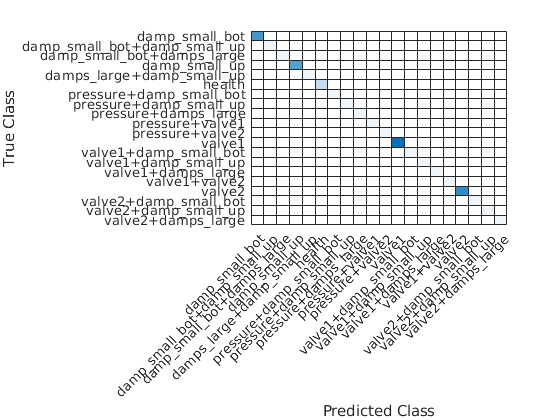

confusion_matrix_plot_handler(mics_anova_model, features)

## Flow Sensors

There are two signals measured:

- Flow Exrusion

- Flow Contraction

addpath("sensor_flow/");
features = load("sensor_flow/FlowsFeaturesAll.mat").FlowsFeaturesAll;
flow_contraction = load("sensor_flow/FlowContractionFineKNN_model.mat").FlowContractionFineKNN_model;
partitionedModel = crossval(flow_contraction.ClassificationKNN, 'Holdout', 0.3);
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError')

validationAccuracy = 0.9711

required_features = flow_contraction.RequiredVariables;
[TrainData, TestData] = split_dataset(features);

new_model = train_flow_KNN(TrainData)

new_model = struct with fields:
           predictFcn: @(x)knnPredictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'FlowContraction_ps_spec/PeakAmp1'  'FlowContraction_ps_spec/PeakAmp3'  'FlowContraction_ps_spec/PeakAmp4'  'FlowContraction_stats/CrestFactor'  'FlowContraction_stats/Mean'}
    ClassificationKNN: [1×1 ClassificationKNN]
                About: 'This struct is a trained model exported from Classification Learner R2021a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an expor

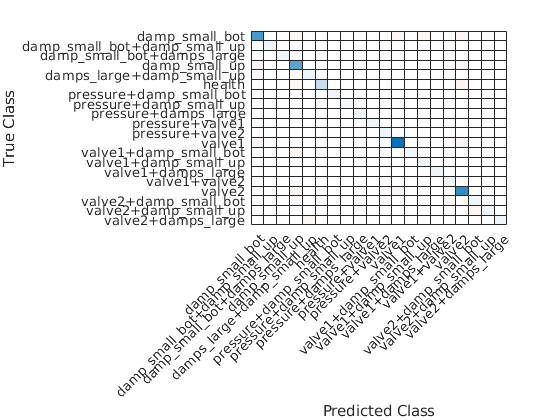

confusion_matrix_plot_handler(new_model, TestData)

## Accelerometer

There are two accelerometer sensors. Each sensor contains two signals in a perpendicular direction. 

One sensor is placed on the movable part of the stand device. The second is on the statical part of the stand device.

## Pressure Sensor

## Proximity Sensors

features = load("sensor_proximity/ProximityAllFeatures.mat").ProximityAllFeatures;
proximity_model_all_features = load("sensor_proximity/ProximityAllFeatures_model.mat").ProximityAllFeatures_model;
partitionedModel = crossval(proximity_model_all_features.ClassificationEnsemble, 'Holdout', 0.3);
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError')

validationAccuracy = 0.8375

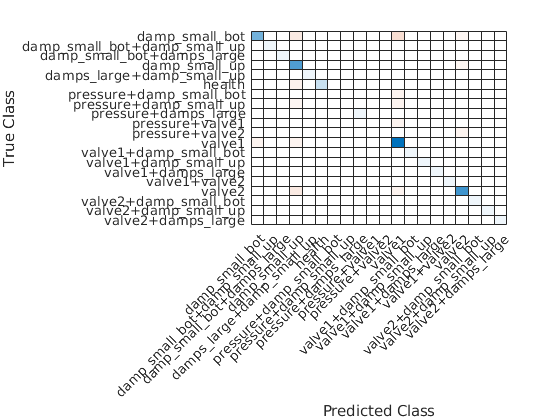

confusion_matrix_plot_handler(proximity_model_all_features, features)

## Strain Gauge

features = load("sensor_strain/StrainAllFeatures.mat").StrainAllFeatures;
strain_model_anova_features = load("sensor_strain/StrainANOVA_model.mat").StrainANOVA_model;
partitionedModel = crossval(strain_model_anova_features.CompactClassificationEnsemble, 'Holdout', 0.3);

Unrecognized field name "CompactClassificationEnsemble".

[validationPredictions, validationScores] = kfoldPredict(partitionedModel);
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError')
confusion_matrix_plot_handler(strain_model_anova_features, features)

## Temperature Sensors

Temperature sensors do only one measurement during the experiment. 

These values can be represented as features. Plotting random data from the dataset shows that they correlated to Ambient temperature different in different measurement days. These data are sensitive to ambient conditions. The classification model trained on this data not robust in real life.

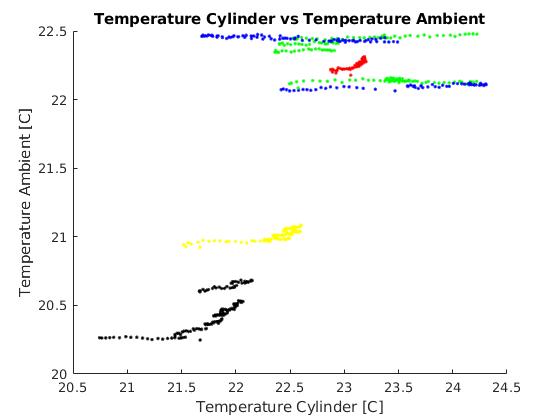

temp_features = load("featuretable/temp_features.mat").temp_features;
figure
hold on
for i = 1:size(temp_features)
    var = temp_features(i,:);
    label = var.Label;
    temp_cylinder = var.Temp_Cylinder;
    temp_ambient = var.Temp_Ambient;
    switch label
        case "health"
            plot(temp_cylinder, temp_ambient, 'r.')
        case "valve1"
            plot(temp_cylinder, temp_ambient, 'g.')
        case "valve2"
            plot(temp_cylinder, temp_ambient, 'b.')
        case "damp_small_bot"
            plot(temp_cylinder, temp_ambient, 'k.')
        case "damp_small_up"
            plot(temp_cylinder, temp_ambient, 'y.')
    end
end
title("Temperature Cylinder vs Temperature Ambient")
xlabel("Temperature Cylinder [C]")
ylabel("Temperature Ambient [C]")

function [dataTrain, dataTest] = split_dataset(data)
    cv = cvpartition(size(data,1), 'HoldOut', 0.3);
    idx = cv.test;      
    dataTrain = data(~idx, :);
    dataTest = data(idx, :);
end

function [] = confusion_matrix_plot_handler(mdl, features)
    required_features = mdl.RequiredVariables;
    targetLabels = features(:,"Label");
    inputTable = features(:, required_features);
    predictedLabels = mdl.predictFcn(inputTable);
    [C,order] = confusionmat(table2array(targetLabels),predictedLabels);
    figure
    confusionchart(C, order)
end